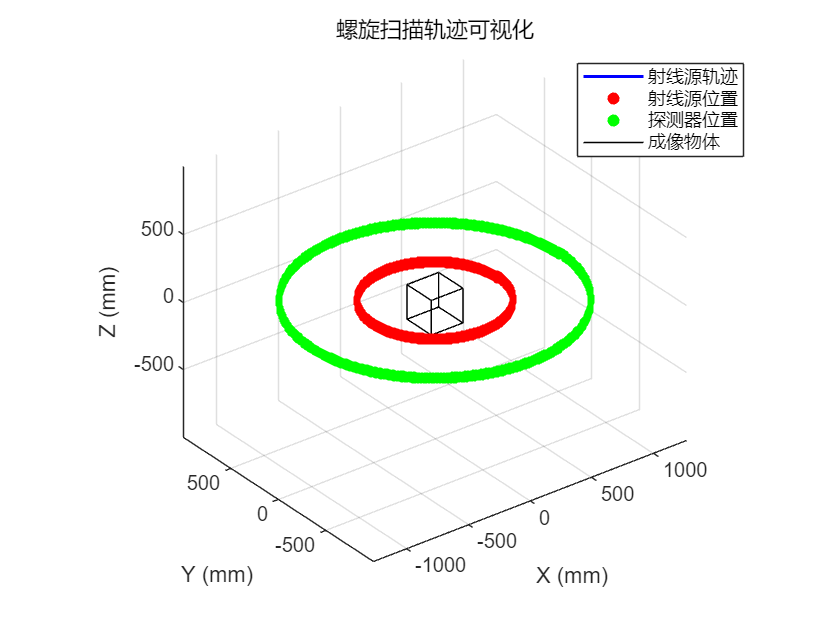

% 添加 TIGRE 路径
addpath(genpath('path_to_TIGRE')); % 替换为 TIGRE 安装路径

% 初始化几何参数
geo = defaultGeometry(); % 使用默认几何参数

% 几何配置
geo.DSD = 1000;       % 射线源到探测器距离 (mm)
geo.DSO = 500;        % 射线源到物体中心距离 (mm)
geo.nVoxel = [256; 256; 256]; % 重建体积大小 (像素)
geo.dVoxel = [1; 1; 1];       % 重建体素尺寸 (mm)

% 探测器配置
geo.nDetector = [512; 512];    % 探测器像素数 (宽 × 高)
geo.dDetector = [0.8; 0.8];    % 探测器像素尺寸 (mm)

% 螺旋扫描轨迹参数
N_turns = 5;              % 螺旋圈数
pitch = 10;               % 每圈螺距 (mm)
N_proj_per_turn = 360;    % 每圈投影数
total_proj = N_turns * N_proj_per_turn; % 总投影数

% 生成扫描角度和 z 轴位置
angles = linspace(0, 2 * pi * N_turns, total_proj); % 扫描角度 (行向量 1×N)
z_positions = linspace(0, N_turns * pitch, total_proj); % z 轴位置 (1×N)

% 射线源和探测器位置计算
source_positions = [geo.DSO * cos(angles); geo.DSO * sin(angles); z_positions]; % 射线源位置 (3×N)
detector_positions = [geo.DSD * cos(angles); geo.DSD * sin(angles); z_positions]; % 探测器位置 (3×N)

% 定义成像物体的矩形框 (以体素中心为参考点)
object_corners = [
    -geo.nVoxel(1)/2, -geo.nVoxel(2)/2, -geo.nVoxel(3)/2;
     geo.nVoxel(1)/2, -geo.nVoxel(2)/2, -geo.nVoxel(3)/2;
     geo.nVoxel(1)/2,  geo.nVoxel(2)/2, -geo.nVoxel(3)/2;
    -geo.nVoxel(1)/2,  geo.nVoxel(2)/2, -geo.nVoxel(3)/2;
    -geo.nVoxel(1)/2, -geo.nVoxel(2)/2,  geo.nVoxel(3)/2;
     geo.nVoxel(1)/2, -geo.nVoxel(2)/2,  geo.nVoxel(3)/2;
     geo.nVoxel(1)/2,  geo.nVoxel(2)/2,  geo.nVoxel(3)/2;
    -geo.nVoxel(1)/2,  geo.nVoxel(2)/2,  geo.nVoxel(3)/2;
] * diag(geo.dVoxel); % 按体素尺寸缩放

% 可视化
figure;
hold on; grid on; axis equal;

% 绘制螺旋扫描轨迹
plot3(source_positions(1, :), source_positions(2, :), source_positions(3, :), 'b-', 'LineWidth', 1.5);

% 绘制射线源位置
scatter3(source_positions(1, :), source_positions(2, :), source_positions(3, :), 10, 'r', 'filled');

% 绘制探测器位置
scatter3(detector_positions(1, :), detector_positions(2, :), detector_positions(3, :), 10, 'g', 'filled');

% 绘制成像物体矩形框
for i = 1:4
    plot3([object_corners(i, 1), object_corners(i+4, 1)], ...
          [object_corners(i, 2), object_corners(i+4, 2)], ...
          [object_corners(i, 3), object_corners(i+4, 3)], 'k-'); % 连接上下平面的点
end
for i = 1:4
    plot3([object_corners(i, 1), object_corners(mod(i, 4)+1, 1)], ...
          [object_corners(i, 2), object_corners(mod(i, 4)+1, 2)], ...
          [object_corners(i, 3), object_corners(mod(i, 4)+1, 3)], 'k-'); % 下平面
    plot3([object_corners(i+4, 1), object_corners(mod(i, 4)+5, 1)], ...
          [object_corners(i+4, 2), object_corners(mod(i, 4)+5, 2)], ...
          [object_corners(i+4, 3), object_corners(mod(i, 4)+5, 3)], 'k-'); % 上平面
end

% 设置图形属性
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('Z (mm)');
title('螺旋扫描轨迹可视化');
legend('射线源轨迹', '射线源位置', '探测器位置', '成像物体');
view(3);
hold off;